# Numerical Methods for Partial Differential Equations

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Partial differential equations appear whenever we describe the relationships between changing functions when the functions depend on more than one independent variable. Partial derivative equations model diffusion, waves, stress/strain, tumor growth, and more. A few of these scenarios allow analytic, closed-form solutions, but in most cases, the solution must be approximated using a numerical method. In situations where the solution is unknown, it is important to clearly understand how much error may be present in a numerical solution. Two types of error contribute to the total error of a numerical solution: roundoff error and discretization error. You must also consider whether your chosen numerical method is stable and will converge to a solution of your differential equation. Finding a numerical solution to a partial differential equation can help you understand the accuracy of your model of the world. 

**Before you get started:**

This live script is intended to be used in Output Inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **( ) using the icons at the top right of the Live Editor pane.

**Background Knowledge:**

If you are unfamiliar with approximating derivatives numerically, please review the [Numerical Derivatives](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Numerical-Methods-with-Applications&project=NumericalMethods.prj&file=Scripts/NumericalDerivatives.mlx&focus=true) discussion in Numerical Methods with Applications before working through this script.

## Numerical methods are used for solving partial differential equations

While it can be intimidating to look at a partial differential equation, the components themselves are straightforward: constants, functions, and partial derivatives, which hold all but one variable constant at a time. This means for a function $T(t,x,y,z)$ the partial derivative with respect to $t$ is defined as:


$$\frac{\partial T}{\partial t} = \lim_{\Delta t \to 0} \frac{T(t+\Delta t,x,y,z)-T(t,x,y,z)}{\Delta t}.$$


The heat equation in a solid is 


$$\rho C_p \frac{\partial T}{\partial t} - \left(\frac{\partial}{\partial x}\left(k\frac{\partial T}{\partial y}\right)+\frac{\partial}{\partial y}\left(k\frac{\partial T}{\partial y}\right)+\frac{\partial}{\partial z}\left(k\frac{\partial T}{\partial z}\right)\right) = g(T,t,x,y,z)$$
    

where $\rho$ is the density and $C_p$ is the heat capacity at constant pressure of the material, $T$ is the temperature, $t$ is the time, $k$ is the thermal conductivity, $g$ tracks the internal heat generated in the system, and $(x,y,z)$ are the spatial coordinates. If $k$ is independent of position, such as in the case of a uniform solid, this equation becomes:

$\rho C_p \frac{\partial T}{\partial t} - k\left(\frac{\partial^2 T}{\partial x^2} + \frac{\partial^2 T}{\partial y^2} + \frac{\partial^2T}{\partial z^2}\right) = g(T,t,x,y,z)$.     $(\mathcal{P})$

**Exercise 1: **Classify the heat equation $\mathcal{P}$.

a. What is the dimension of $\mathcal{P}$?

dimP = "unknown";

b. What is the order of $\mathcal{P}$?

orderP = "unknown";

c. Is $\mathcal{P}$ linear or nonlinear?

linearityOfP = "unknown"
 
CheckEx1(dimP,orderP,linearityOfP)

## Discretization error is a property of the problem and the method

As with all numerical methods, the first step is to decide how a problem will be discretized. We can break this down into two parts: discretizing the domain of the problem and discretizing the partial differential equation. 

### Discretizing the variables to create a mesh on the domain

Each independent variable in the problem must be subdivided into a discrete set of points. Combining all of these possible values generates a mesh covering the domain. Many problems will involve a bounded physical domain and a half-infinite time domain, $t>0$, on which to solve. A boundary value, $t_{\text{End}}$, must be chosen to discretize the domain. The initial data will contain information about known values of the dependent variable on the boundary of this mesh. 

Different numerical methods operate on different forms of mesh, but all of them have to start with some form of discretization.

### Discretizing the equation using approximations of the derivatives

The other aspect of a numerical method is discretizing the partial differential equation itself to create a solvable system of equations. The method of finite differences approaches the problem by numerically approximating each derivative and using relationships between values on the mesh to determine systems of linear equations that can be solved for the values of the dependent variable.

The method of finite elements discretizes the space of possible solutions into localized test functions that can also be used to create a system of linear equations. In this case, the system of linear equations calculates the coefficients of each test function in the overall solution to the problem. 

## Implement finite difference methods

If we try to explore problem $\mathcal{P}$, we will quickly run into visualization challenges, such as the fact that the domain of the solution is 4-dimensional, and repetition, such as the similarity in $x$, $y$, and $z$ that add length to the problem without offering new learning. If we simplify the 3-dimensional heat equation $(\mathcal{P})$ into a one-dimensional heat equation modeling heat in a uniform rod of length $L$ with no internally generated heat, this will reduce the solution domain to being a 2-dimensional rectangle and leave a single first-order partial derivative and a single second order partial derivative. This becomes 

        $\frac{\partial u}{\partial t} = \gamma \frac{\partial^2u}{\partial x^2}$,        $(\mathcal{H})$

where $\gamma = \frac{k}{\rho C_p} > 0$ is the thermal diffusivity. Because this equation is first-order in time, we will need information about the value of the function at a particular time, $u(t_0,x) = f(x)$. However, the equation is second order in space, so we will need to know the Dirichlet boundary conditions, $u(t,0) = \alpha(t)$ and $u(t,L) = \beta(t)$, or we will need to know the Neumann boundary conditions, $u_x(t,0) = \alpha(t)$ and $u_x(t,0) = \beta(t)$ where $u_x = \frac{\partial u}{\partial x}$, or some combination to have a well-defined problem.  

### Example: Explicit Method

#### Step 1: Discretize the problem

Let's use a constant rectangular mesh discretization. This means we must choose a step size $\Delta t$, to move forward in time and a step size $\Delta x = \frac{L}{n}$ dividing the spatial domain into $n$ intervals. Now our domain looks like this:

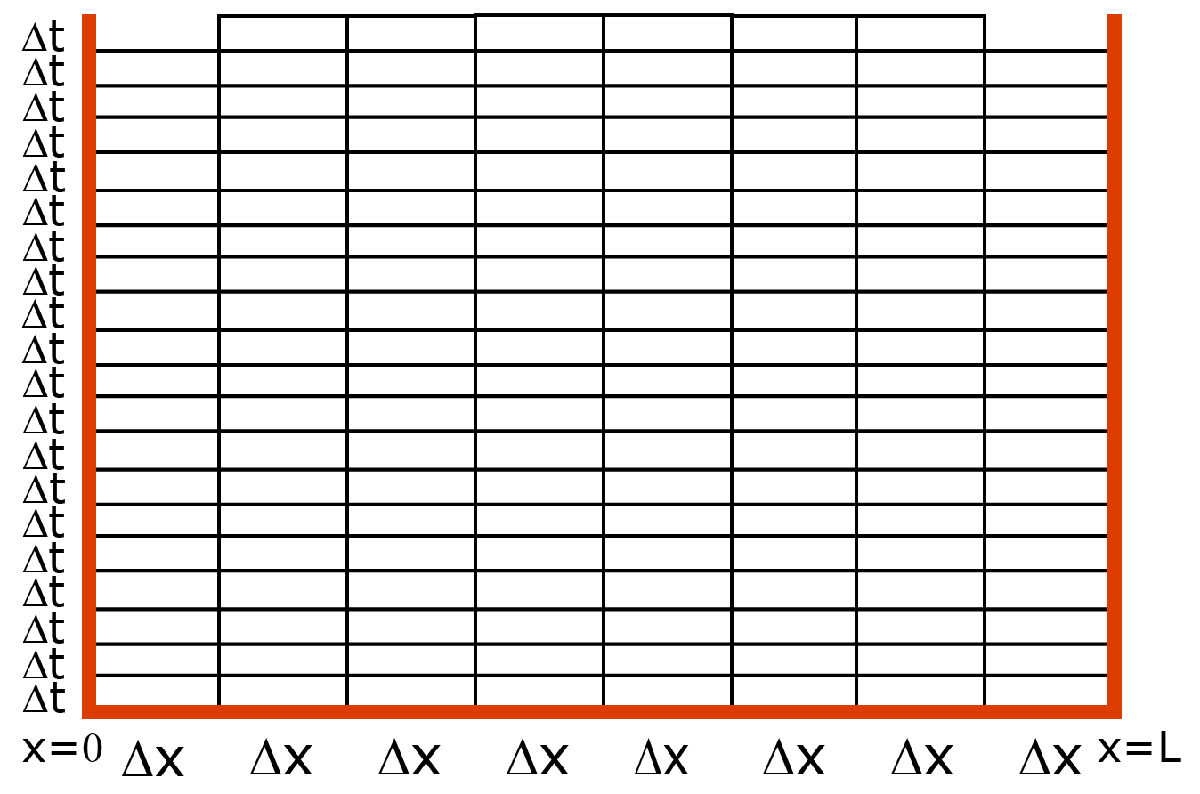

Note that we know the value of our solution, $u(t,x)$, around three edges of the domain: $u(t_0,x) = f(x)$, $u(t,0) = \alpha(t)$, and $u(t,L) = \beta(t)$. That leaves a mesh of interior values that we want to solve for. 

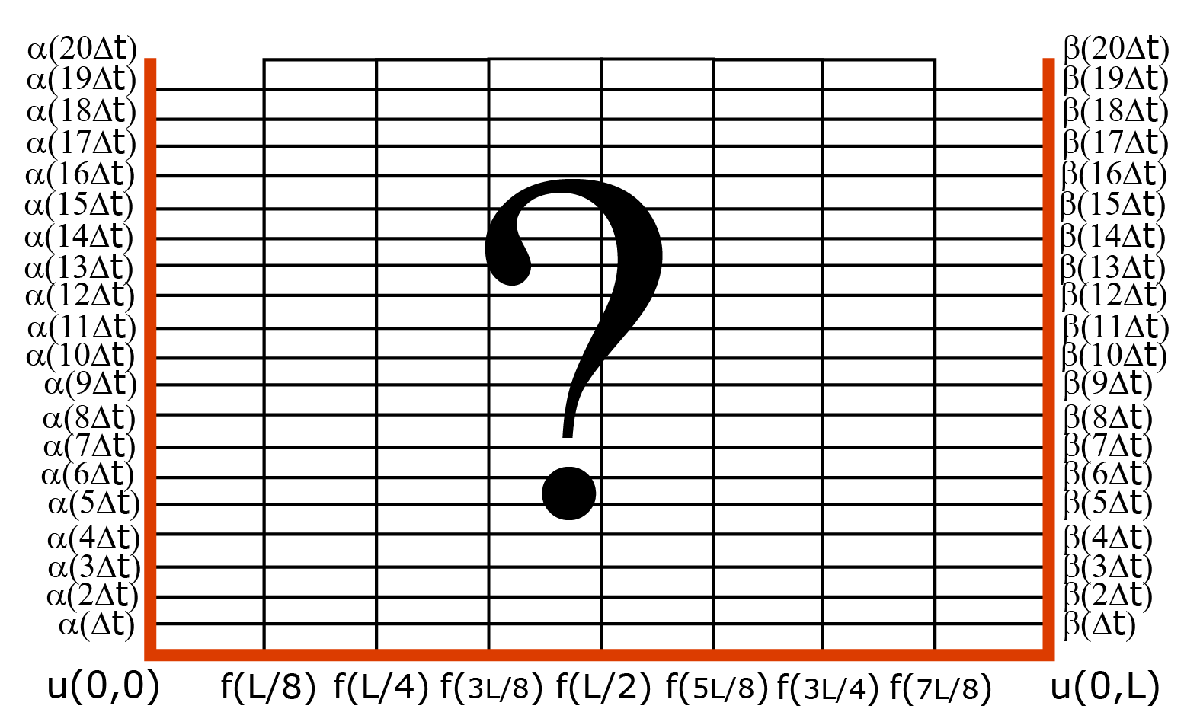

For ease of notation, let's denote the point $u(t_j,x_m) = u_{j,m}$ where $t_j = t_0+j\Delta t$ and $x_j = j\Delta x$ where $j \geq 0$ and $m \in \{0,1,2,\ldots,n\}$. In this formulation, we know $u_{0,m} = f_m = f(x_m)$, $u_{j,0} = \alpha_j = \alpha(t_j)$, and $u_{j,n} = \beta_j = \beta(t_j)$. The values that we do not know are $u_{j,m}$ for $j > 0$ and $m \in \{1,2,\ldots,n-1\}$. 

#### Step 2: Discretize the method

There are two derivatives in equation $(\mathcal{H})$, so we must choose an approximation for $\frac{\partial u}{\partial t}$ and an approximation for $\frac{\partial^2u}{\partial x^2}$. There are many possible choices for each approximation. Still, each has tradeoffs between how complex it is to implement, how much error it will introduce, and whether the solution will be useful. 

A straightforward choice is to use a first-order forward difference approximation for the time derivative, 

$\frac{\partial u}{\partial t}(t_j,x_m) \approx \frac{u(t_j+\Delta t,x_m)-u(t_j,x_m)}{\Delta t} = \frac{u_{j+1,m}-u_{j,m}}{\Delta t}$, 

on mesh points and for the spatial derivative, let's use a second-order centered difference approximation

$\frac{\partial^2u}{\partial x^2}(t_j,x_m) \approx \frac{u(t_j,x_{m+1})-2u(t_j,x_m)+u(t_j,x_{m-1})}{(\Delta x)^2} = \frac{u_{j,m+1}-2u_{j,m}+u_{j,m-1}}{(\Delta x)^2}$.

Plugging these into the differential equation, we find:

$\frac{u_{j+1,m}-u_{j,m}}{\Delta t} = \gamma\left(\frac{u_{j,m+1}-2u_{j,m}+u_{j,m-1}}{(\Delta x)^2}\right)$, 

which simplifies to


$$u_{j+1,m} =  u_{j,m}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,m+1}-2u_{j,m}+u_{j,m-1}\right).$$
   
$$(\mathcal{E})$$


Because we know all of the values $u_{0,m} = f_m$, we can estimate the values of $u_{1,m}$ and then use those values to estimate $u_{2,m}$ and so forth. 

#### Step 3: Check the stability of this method

A valid numerical approximation will eventually converge toward the solution. As you may remember from discussions of limiting behavior, however, not every method will converge. Some methods may bounce around in a bounded region around the solution, which may be sufficiently precise, while others may get farther and farther away no matter how small a step size is chosen.

One way to test the stability of a method is Fourier stability analysis. Suppose we assume that there is a Fourier series representation of the solution. In that case, each complex Fourier mode, $e^{ikx}$, is an eigenfunction of the differential equation with eigenvalue $\lambda$ representing the scaling factor applied by each step forward in time.  This means that if $u(t,x) = e^{ikx}$ then $u(t+\Delta t,x) = \lambda e^{ikx}$.

Let $u_{j,m} = u(t_j,x_m) = e^{ikx_m}$, where $k$ is a real parameter selecting the mode. Plugging into our approximation, we have:


$$u_{j+1,m} =  u_{j,m}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,m+1}-2u_{j,m}+u_{j,m-1}\right)$$
     


$$\lambda e^{ikx_m}= e^{ikx_m}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(e^{ikx_{m+1}}-2e^{ikx_m}+e^{ikx_{m-1}}\right)$$


                
$$= e^{ikx_m}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(e^{ik(x_m+\Delta x)}-2e^{ikx_m}+e^{ik(x_m-\Delta x)}\right)$$


Because $e^{ikx_m} \neq 0$, we can divide the entire equation by the Fourier mode, leaving us with:


$$\lambda = 1+ \frac{\gamma \Delta t}{(\Delta x)^2}\left(e^{ik\Delta x}-2+e^{-ik\Delta x}\right)$$
          

$=1 - 2\frac{\gamma \Delta t}{(\Delta x)^2}\left(1- \frac{e^{ik\Delta x}+e^{-ik\Delta x}}{2}\right)$.

Using trigonometric identities, we see that


$$= 1-2\frac{\gamma \Delta t}{(\Delta x)^2}\left(1-\cos(k\Delta x)\right)$$
         

$=1-4\frac{\gamma\Delta t}{(\Delta x)^2}\sin^2\left(\frac{k\Delta x}{2}\right)$.              

Therefore, $|\lambda| \leq 1$ if 


$$-1 \leq 1-4\frac{\gamma\Delta t}{(\Delta x)^2}\sin^2\left(\frac{k\Delta x}{2}\right) \leq 1$$



$$-2 \leq-4\frac{\gamma\Delta t}{(\Delta x)^2}\sin^2\left(\frac{k\Delta x}{2}\right) \leq 0$$


$\frac{1}{2} \geq \frac{\gamma\Delta t}{(\Delta x)^2}\sin^2\left(\frac{k\Delta x}{2}\right) \geq 0$.

This gives us a relationship between the chosen step sizes $\Delta t$ and $\Delta x$. As long as $\frac{(\Delta x)^2}{2\gamma} \geq \Delta t$, every eigenfunction in the Fourier series for $u$ will be stable at each step of the estimate so the approximation will not diverge. 

#### Step 4: Formulate the linear algebra problem 

While it is possible to apply the method in equation $(\mathcal{E})$ by hand, it is much more efficient to solve for all the values at each time step at once by expressing the relations as a linear system of equations. 


$$u_{j+1,1} =  u_{j,1}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,2}-2u_{j,1}+u_{j,0}\right)$$



$$u_{j+1,2} =  u_{j,2}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,3}-2u_{j,2}+u_{j,1}\right)$$



$$u_{j+1,3} =  u_{j,3}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,4}-2u_{j,3}+u_{j,2}\right)$$



$$\vdots$$



$$u_{j+1,m} =  u_{j,m}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,m+1}-2u_{j,m}+u_{j,m-1}\right)$$



$$\vdots$$



$$u_{j+1,n-1} =  u_{j,n-1}  + \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j,n}-2u_{j,n-1}+u_{j,n-2}\right)$$


Let $\mu = \frac{\gamma \Delta t}{(\Delta x)^2}$ be the multiplier that appears repeatedly in these equations. If we create vectors $\vec{u}^{(j+1)} = \pmatrix{u_{j+1,1} \cr u_{j+1,2} \cr u_{j+1,3} \cr \vdots \cr u_{j+1,n-2} \cr u_{j+1,n-1}}$, where $\vec{u}^{(0)} = \pmatrix{f_1 \cr f_2 \cr f_3 \cr \vdots \cr f_{n-2} \cr f_{n-1}}$ and $\vec{b}^{(j)} = \pmatrix{ \mu \alpha_j \cr 0 \cr 0 \cr \vdots \cr 0 \cr \mu\beta_j}$ encode the initial conditions, then the matrix $A = \pmatrix{1-2\mu & \mu & & & &  \cr \mu & 1-2\mu & \mu & && \cr & \mu & 1-2\mu & \mu && \cr &&\mu&\ddots & \ddots & \cr &&& \ddots & \ddots & \mu \cr &&&& \mu & 1-2\mu}$ relates the entire system.

$\vec{u}^{(j+1)} = A\vec{u}^{(j)} + \vec{b}^{(j)}$.

#### Step 5: How good is our estimate?

The error analysis of derivative approximations shows us that 

$\frac{\partial u}{\partial t}(t_i,x_j) = \frac{u(t_i+\Delta t,x_j)-u(t_i,x_j)}{\Delta t} + \mathcal{O}(\Delta x)$, 

and

$\frac{\partial^2u}{\partial x^2}(t_i,x_j) = \frac{u(t_i,x_{j+1})-2u(t_i,x_j)+u(t_i,x_{j-1})}{(\Delta x)^2} + \mathcal{O}\left((\Delta x)^2\right)}$.

To ensure the best results with a given step size $\Delta x$, we need the error contributions due to estimations on each side of the differential equation to be of comparable magnitude.  This means that 

$\mathcal{O}(\Delta t) \approx \mathcal{O}\left((\Delta x)^2\right)$, 

or in other words, we have to choose

$\Delta t \approx (\Delta x)^2$.

To use a finer resolution, say $\displaystyle \frac{\Delta x}{10}$, in our spatial solution, we have to take much smaller time steps, say $\frac{\Delta t}{100}$. 

### Implement an explicit method

**Exercise 2:**

Work through unit tests for the components of `ExplicitPDE.m`.

edit ImplementExplicitSolver.mlx

Write the function `ExplicitPDE` to implement the solution method to 1D heat equations presented in this example.

edit ExplicitPDE.m

Test your function by using it to solve a problem.

% Define the parameters and boundary functions for the problem
L = 4;                   % Length of the rod
gamma = 3;               % Diffusivity, gamma > 0
dx = 0.1;                % Spatial step size
tEnd = 0.15;             % The time at which to finish the approximation
f = @(x) x.^2-4.*x;      % u(0,x)
alpha = @(t) sin(100*t); % u(t,0)
% Using the piecewise function requires a symbolic function
syms betaFunc(t)
betaFunc(t) = piecewise((0 <= t) & (t < 0.5), ...
    t,(0.5 <= t) & (t <= 1),1-t,0);       % u(t,L)
% To ensure that the output of beta is a double
beta = @(t) double(betaFunc(t));

u = ExplicitPDE(f,alpha,beta,tEnd,dx,gamma,L);

Plot the initial value `u0` and the final value` u` on the same plot.

plot(0:dx:L,f(0:dx:L))
hold on
plot(0:dx:L,[alpha(tEnd);u;beta(tEnd)])
hold off
title("Solving $\frac{\partial u}{\partial t} = \gamma \frac{\partial^2 u}{\partial x^2}$","Interpreter","latex")
subtitle("$t=$"+tEnd,"Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$u$","Interpreter","latex")
legend(["u(0,x)" "u(t,x)"],"Location","north")

**Reference Output**

With $L=4$, $\Delta x=0.1$, and $\frac{\partial u}{\partial t} = 3\frac{\partial^2u}{\partial x^2}$ with $u(0,x) = x^2-4x$, $u(t,0)=\sin(100t)$ and $u(t,4) = \begin{cases} t & 0 \leq t < 0.5 \\ 1-t & 0.5 \leq t < 1 \\ 0 & \text{else} \end{cases}$, you should have the following results at $t=0.05$, $t= 0.1$, $t=0.15$ and $t=0.2$.

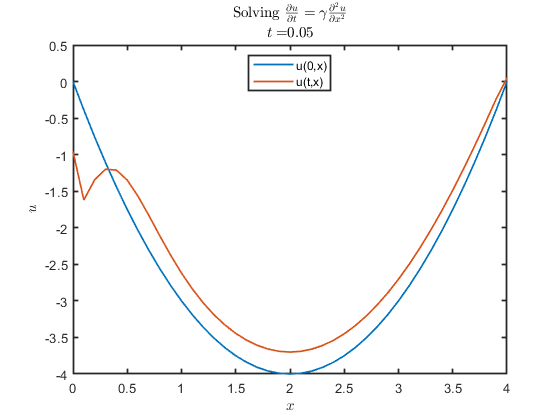   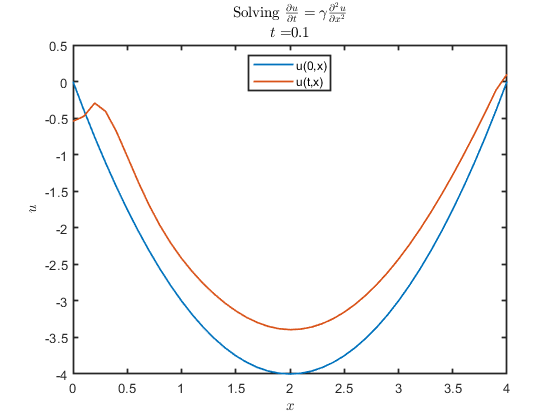

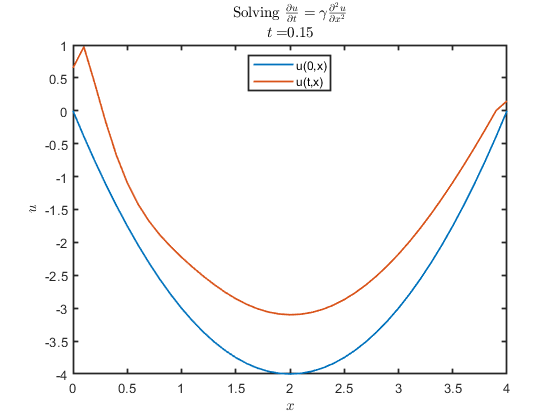   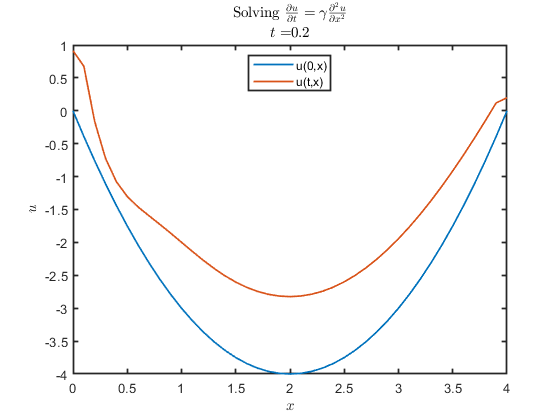

### Example: Implicit Methods

As with numerical methods for ordinary differential equations, implicit solution methods for partial differential equations require solving systems of equations. Taking the same 1D heat equation $(\mathcal{H})$ and the same discretization of the variables, as with the explicit method example, we can begin by discretizing the equation in a different way.

#### Step 1: Discretizing the equation using approximations of the derivatives

Rather than a forward difference approximation for $\frac{\partial u}{\partial t}$, in this case, use a first-order backward difference equation,

$\frac{\partial u}{\partial t}(t_j,x_m) \approx \frac{u(t_j,x_m)-u(t_j-\Delta t,x_m)}{\Delta t} = \frac{u_{j,m}-u_{j-1,m}}{\Delta t}$, 

on mesh points. For the spatial derivative, let's use the same second-order centered difference approximation that we did in the explicit method example. Shifting values from $j$ to $j+1$ so we don't try to refer to $u_{-1}$ when $j=0$, and plugging these into the differential equation, we find:

$\frac{u_{j+1,m}-u_{j,m}}{\Delta t} = \gamma\left(\frac{u_{j+1,m+1}-2u_{j+1,m}+u_{j+1,m-1}}{(\Delta x)^2}\right)$, 

which simplifies to

$u_{j+1,m} -  \frac{\gamma \Delta t}{(\Delta x)^2}\left(u_{j+1,m+1}-2u_{j+1,m}+u_{j+1,m-1}\right)=  u_{j,m}$.   $(\mathcal{I})$

#### Step 2: Check the stability of this method

** Exercise 3:** 

Follow the example of the Fourier stability analysis of the explicit method $(\mathcal{E})$ to compute the Fourier stability of the implicit method $(\mathcal{I})$. 

**Pro Tip: **To type equations in a live script you can either use "Insert Equation" in the Insert tab of the toolstrip or you can use LaTeX notation directly.

**Solution: **

#### Step 3: Formulate the linear algebra problem 

Since we have chosen to use the same discretization of the problem, we can use the same vector $\vec{u}^{(j)} = \pmatrix{u_{j,1}\cr \vdots \cr u_{j,n-1}}$ as before. In terms of $\vec{u}^{(j+1)}$ and $\vec{u}^{(j)}$, the entire system of equations $(\mathcal{I})$ relating times $t_j$ and $t_{j+1}$ are given by 

$B\vec{u}^{(j+1)} - \vec{b}^{(j+1)} = \vec{u}^{(j)}$,

or in other words, 

$\vec{u}^{(j+1)} = B^{-1}\left(\vec{u}^{(j)}+\vec{b}^{(j+1)}\right)$,

where $B = \pmatrix{1+2\mu & -\mu & & & &  \cr -\mu & 1+2\mu & -\mu & && \cr & -\mu & 1+2\mu & -\mu && \cr && -\mu&\ddots & \ddots & \cr &&& \ddots & \ddots & -\mu \cr &&&& -\mu & 1+2\mu}$ and $\vec{b}^{(j+1)} = \pmatrix{\mu\alpha_{j+1}\cr 0 \cr 0 \cr \vdots \cr 0 \cr \mu\beta_{j+1}}$. 

#### Step 4: How good is our estimate?

** Exercise 4.**

Follow the error calculation in the explicit method example to determine an appropriate relationship between `dt` and `dx` to control the derivative approximation error.

% Enter the correct relationship here
dt = dx;


### Implement an implicit method

** Exercise 5.**

Implement the implicit method $(\mathcal{I})$. 

open ImplicitPDE.m

Test your function by solving the same problem as the explicit method.

u = ImplicitPDE(f,alpha,beta,tEnd,dx,gamma,L);

Plot the initial value `u0` and the final value` u` on the same plot.

plot(0:dx:L,f(0:dx:L),"LineWidth",4)
hold on
plot(0:dx:L,[alpha(tEnd);u;beta(tEnd)],"LineWidth",4)
hold off
title("Solving $\frac{\partial u}{\partial t} = \gamma \frac{\partial^2 u}{\partial x^2}$","Interpreter","latex")
subtitle("$t=$"+tEnd,"Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$u$","Interpreter","latex")
legend(["u(0,x)","u(t,x)"],"Location","north")

**Reference Output**

With $L=4$, $\Delta x=0.1$, and $\frac{\partial u}{\partial t} = 3\frac{\partial^2u}{\partial x^2}$ with $u(0,x) = x^2-4x$, $u(t,0)=\sin(100t)$ and $u(t,4) = \begin{cases} t & 0 \leq t < 0.5 \\ 1-t & 0.5 \leq t < 1 \\ 0 & \text{else} \end{cases}$, you should have the following results at $t=0.05$, $t= 0.1$, $t=0.15$ and $t=0.2$.

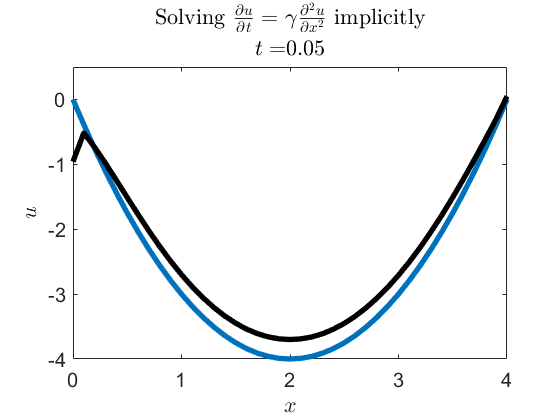   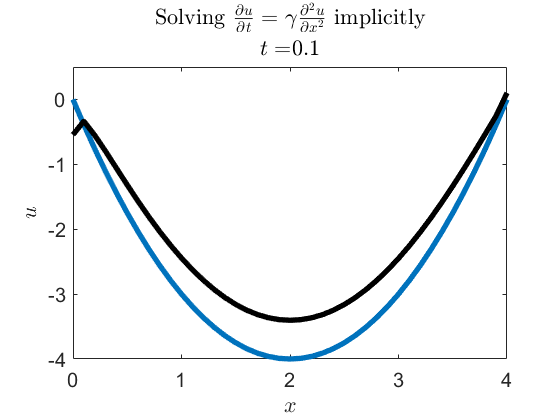

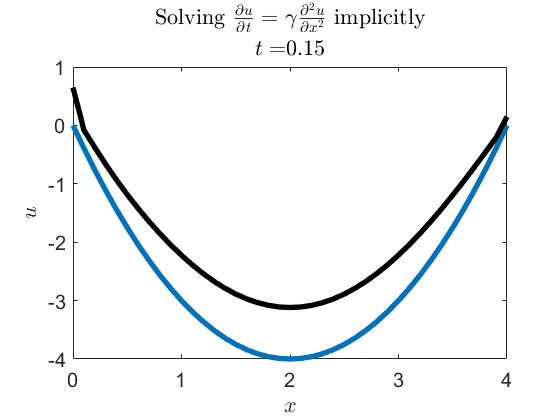   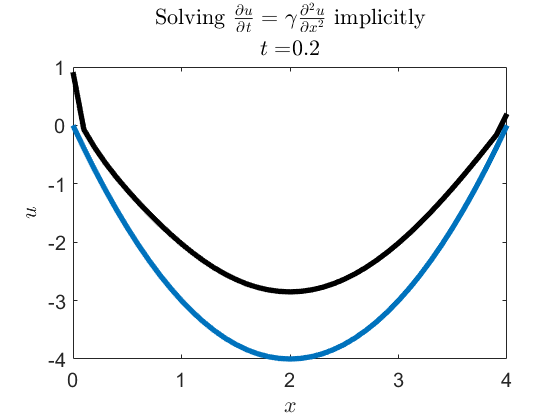

 **Reflect**.

- Use [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) to quantify the improvement in calculation time from the explicit to the implicit method in this case.

- What are the tradeoffs between the explicit and implicit methods? Is one method consistently superior?

### Implement the Crank-Nicolson Method

** Exercise 6.**

Implement the Crank-Nicolson method, which uses a trapezoidal integral approximation. This is equivalent to the average of the explicit method $(\mathcal{E})$ and the implicit method $(\mathcal{I})$, literally $\frac{(\mathcal{E})+(\mathcal{I})}{2}$.

open CN.m

Then, call CN using the same function as before. Do you get a similar result?

% Write your code for calling CN here


 **Reflect**.

- What are the restrictions on the step size `dt` due to error from the derivative approximations?

- What are the restrictions on the step size `dt` due to stability requirements?

- Could you utilize what you know about derivative approximations to make a different explicit or implicit method to solve this equation?

**Reference Output**

With $L=4$, $\Delta x=0.1$, and $\frac{\partial u}{\partial t} = 3\frac{\partial^2u}{\partial x^2}$ with $u(0,x) = x^2-4x$, $u(t,0)=\sin(100t)$ and $u(t,4) = \begin{cases} t & 0 \leq t < 0.5 \\ 1-t & 0.5 \leq t < 1 \\ 0 & \text{else} \end{cases}$, you should have the following results at $t=0.05$, $t= 0.1$, $t=0.15$ and $t=0.2$.

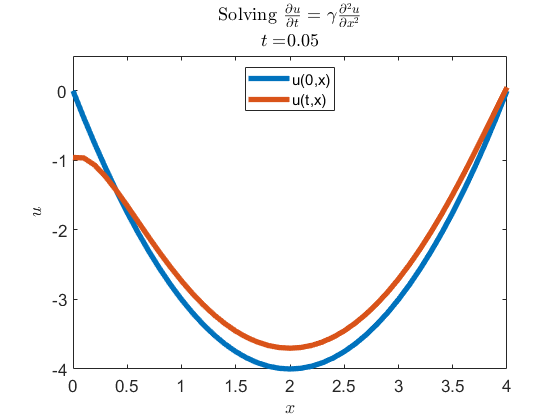   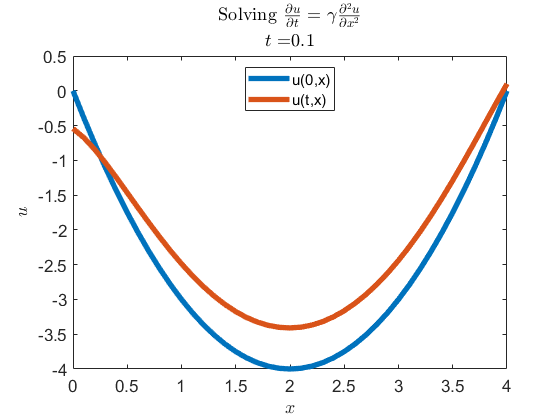

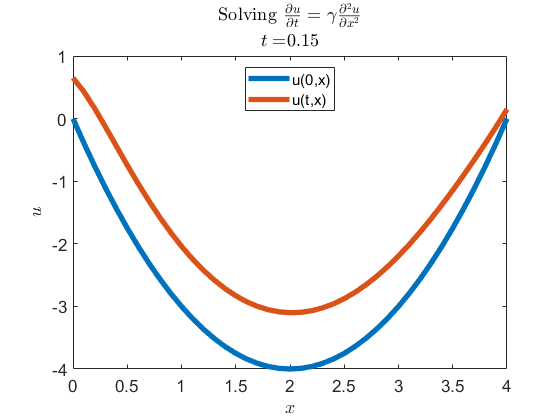   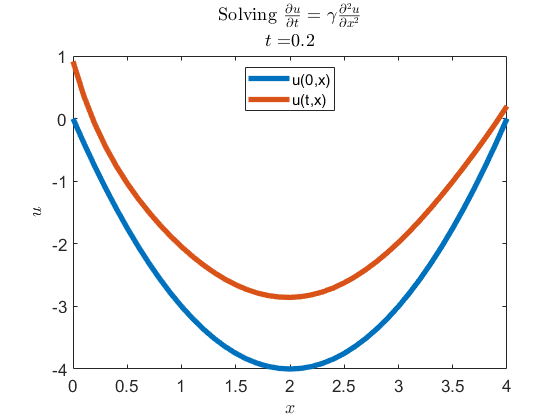

## Apply numerical methods

### Mix and match

While the Crank-Nicolson method has many desirable features among the three methods you have implemented, it also has some negatives. Specifically, while diffusive equations such as heat immediately smooth out corners, the Crank-Nicolson method preserves corners, as shown in the reference output. Even as the overall shape is smoothing, the point where the original function had a discontinuous derivative continues to appear in the numerical solution with a discontinuous derivative. Consider the following equation:

$\frac{\partial u}{\partial t} = \gamma \frac{\partial^2 u}{\partial x^2}$  with boundary conditions $\begin{cases} u(0,x) = f(x) & \\ u(t,0) = \alpha(t) & \\ u(t,L) = \beta(t) & \end{cases}$

% Define the parameters and boundary functions for the problem
L = 4;                   % Length of the rod
gamma = 1;               % Diffusivity, gamma > 0
dx = 0.01;               % Spatial step size
tEnd = 0.08;             % The time at which to finish the approximation
syms fFunc(x)
fFunc(x) = piecewise(x<=1,2*x,(x>1)&(x<=2),5-3*x,...
    (x>2)&(x<=3),-1,(3<x),2*x-7)
f = @(x) double(fFunc(x));      % u(0,x)
alpha = @(t) 0;                 % u(t,0)
beta = @(t) 1;                  % u(t,L)
plot(0:dx:L,f(0:dx:L))

**Reference Output**

With $L=4$, $\Delta x=0.1$, and $\frac{\partial u}{\partial t} = \frac{\partial^2u}{\partial x^2}$ with $u(0,x) = \begin{cases} 2x & x \leq 1 \\ 5-3x & 1 < x \leq 2 \\ -1 & 2 < x \leq 3 \\ 2x-7 & 3 < x \end{cases} $, $u(t,0)=0$ and $u(t,4) = 1$, at $t=0.01$ and $t=0.02$ we have:

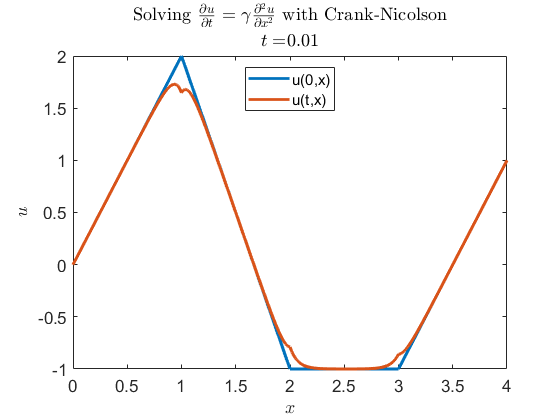   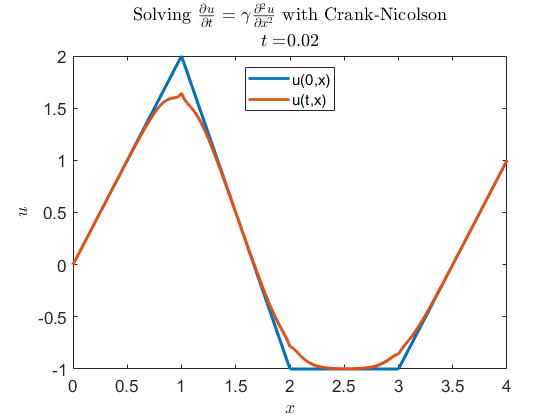

  **Try**. Can you reproduce this output? 

uCN = CN(f,alpha,beta,tEnd,dx,gamma,L);

  **Try**. What results do you find using the explicit solution method? 

figure
uExp = ExplicitPDE(f,alpha,beta,tEnd,dx*100,gamma,L);

  **Try**. What results do you find using the implicit solution method? 

figure
uImp = ImplicitPDE(f,alpha,beta,tEnd,dx*100,gamma,L);

As you can see, the Crank-Nicolson method generates smooth curves everywhere except close to points where the initial data had a corner. To observe both long and short timescales, it can be the most efficient to mix methods such as using a pure implicit method with a small timestep $\Delta t \approx (\Delta x)^2$ for a short time and then switching to a comparable-error method with a longer potential timestep such as Crank-Nicolson with $\Delta t\approx \Delta x$ to observe longer-term behavior.

** Exercise 7.**

Make a new version of CN that you call CN`u0`. In this version, instead of the initial data `t0` and `u0` being computed as `t0 = 0` and `u0 =` `f(x)`, they are provided as arguments to the function. 

Test the combined output by uncommenting the code below and running ImplicitPDE for `t < 0.01`, and CN`u0` for `0.01 < t < 5`. 

% tEnd1 = 0.01;
% dx = 0.01;
% tFinal = 5;
% u1 = ImplicitPDE(f,alpha,beta,tEnd1,dx,gamma,L);
% hold on
% u = CNu0([alpha(tEnd1);u1;beta(tEnd1)],alpha,beta,tFinal,dx,gamma,L,tEnd1);
% hold off

## Further Explorations

### Solving systems of PDEs

Just as it is possible to extend first-order ODE solvers to solve systems of ODEs, it is also possible to extend PDE solvers to handle systems of PDEs. 

[Modeling tumor-related angiogenesis](https://www.mathworks.com/help/matlab/math/solve-angio-pde-system.html)

### Partial Differential Equations Toolbox

Another common approach to numerically solving differential equations, especially with complicated geometry, is discretizing the spatial domain using triangles and the method in function space. This finite element method takes more mathematical background to understand but is commonly used in applications. 

[Thermal Stress Analysis of Jet Engine Turbine Blade](https://www.mathworks.com/help/pde/ug/thermal-stress-analysis-of-jet-engine-turbine-blade.html)

This example presents working with complicated geometry loaded from a CAD design program while modeling heat transfer.

[Helmholtz Equation on Disk with Square Hole](https://www.mathworks.com/help/pde/ug/helmholtzs-equation-on-disk-with-a-square-hole.html)

This example solves a 2-D wave equation on a circle with an obstruction in the center.

[Deflection Analysis of Bracket](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

This example computes the deflection and stress of a simple mounted bracket with a localized downward force applied.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

### Local Functions

function CheckEx1(a,b,c)
arguments
    a (1,1) string {mustBeMember(a,["unknown" "1D" "2D" "3D" "4D"])}
    b (1,1) string {mustBeMember(b,["unknown" "first" "second" "third" "fourth"])}
    c (1,1) string {mustBeMember(c,["unknown" "linear" "nonlinear"])}
end
if a == "unknown"
    disp("This is the default value of the dimensionality." + newline + "Please select the correct option.")
elseif a == "3D"
    disp("Part a) is correct. "+newline+"There are three spatial dimensions in this problem: x, y, and z")
elseif a == "4D"
    disp("Part a) is incorrect." + newline + "That would make sense, but by convention PDEs are labeled by their spatial dimensions." + newline + "Please try again.")
else
    disp("Part a) is incorrect." + newline + "How many spatial dimensions are in this problem?")
end

if b == "unknown"
    disp("This is the default value of the order."+ newline + "Please select the correct option.")
elseif b == "second"
    disp("Part b) is correct." + newline + "Yes, this is a second order PDE.")
else
    disp("Part b) is incorrect." + newline + "No, this is not a " + b + " order PDE." + newline + "Please try again.")
end

if c == "unknown"
    disp("This is the default value of the linearity." + newline + "Please select the correct option.")
elseif c == "linear"
    disp("Part c) is correct.")
else
    disp("Part c) is incorrect. Please try again.")
end
end

%#ok<*INUSL> 
%#ok<*INUSD> 